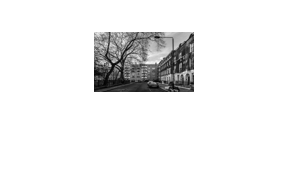


img = imread('C:\Users\Harish\Downloads\ITC_img.png');           % Original image
img = imresize(img,[60,100]);           % Resolution decreased to have a reasonable execution time
%img = rgb2gray(img);            % Since original image has three channels, converting it into black and white          
imshow(img);

bitstream = [];
[row col] = size(img)

row = 60

col = 100

for i=1:row                            % Reorganizing image into a bitstream
    for j=1:col
        l = dec2bin(img(i,j),8);
        for k=1:8
            bitstream = [bitstream str2num(l(k))];
        end
    end
end

b = bitstream;
k = 2;
G = [1 0 1 1 0;
     0 1 0 1 1];
H = [1 0 1 0 0
     1 1 0 1 0
     0 1 0 0 1];
T = syndtable(H)

Single-error patterns loaded in decoding table.  2 rows remaining.
2-error patterns loaded.  0 rows remaining.


T =      0     0     0     0     0
     0     0     0     0     1
     0     0     0     1     0
     0     1     0     0     0
     0     0     1     0     0
     1     1     0     0     0
     1     0     0     0     0
     1     0     0     0     1


l = length(b);
b_encoded = [];
for i=1:2:l
    input = [b(i) b(i+1)];
    output = mod(input*G,2);                     % Channel Coding
    b_encoded = [b_encoded output];
end
p = rand(1,length(b_encoded));
b_e = xor(b_encoded,(p>=0.9))

b_e = 1×120000 logical array
   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   1   0   1   1   0   1   1   1   0   1   0   0   0   0   0



ed = 0;
corrected_b = [];
l = length(b_e);      
for j=1:5:l                                         % Error Correction
    v = [b_e(j) b_e(j+1) b_e(j+2) b_e(j+3) b_e(j+4)];
    s = mod(v*H',2);
    if(norm(s,1)~=0)
        ed = ed + 1;
        dec = s(1)*4 + s(2)*2 + s(3);
        g_e = T(dec+1,:);
        c_v = xor(g_e,v);
    else
        c_v = v;
    end
    corrected_b = [corrected_b c_v];
end
error = norm(b_e - b_encoded,1);     % Error before correction , number of bits
error_c = norm(corrected_b-b_encoded,1) ; % Error after correction , number of bits
ed

ed = 9768

error

error = 11998

error_c

error_c = 5148

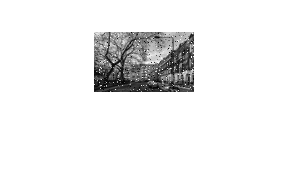


data_r = [];                  
for k=1:5:length(corrected_b)  
    data_r = [data_r corrected_b(k) corrected_b(k+1)];  % Data bits received
end

pixel_val = [];
for a=1:8:length(data_r)
    pixel_val = [pixel_val (data_r(a)*2^7 + data_r(a+1)*2^6 + data_r(a+2)*2^5 + data_r(a+3)*2^4 + data_r(a+4)*2^3 + data_r(a+5)*2^2 + data_r(a+6)*2^1 + data_r(a+7))];%  Combining sets of 8 bits to get intensity values
end

img_r = [];
for l = 1:row
    for m = 1:col
        img_r(l,m) = pixel_val((l-1)*col+m); % Reconstructing image from pixel values
    end
end
img_r = uint8(img_r);
imshow(img_r)